code adapted from https://www.mathworks.com/help/deeplearning/ug/train-deep-learning-network-to-classify-new-images.html

Download images from computer

clc; clear;
downloadFolder = tempdir;
%change the following line to your image location
imageFolder='\\client\c$\Users\allis\Documents\Comp Apps\Final Project\brain_tumor_dataset'

imageFolder = '\\client\c$\Users\allis\Documents\Comp Apps\Final Project\brain_tumor_dataset'

imds = imageDatastore(imageFolder, 'LabelSource', 'foldernames', 'IncludeSubfolders',true);
tbl = countEachLabel(imds)

tbl = 2×2 table
    Label    Count
    _____    _____

     no        98 
     yes      155 


Determine the smallest amount of images in a category and trim the data so each category has the same number of images

minSetCount = min(tbl{:,2}); 
imds = splitEachLabel(imds, minSetCount, 'randomize');

Load pretrained network GoogLeNet

net = googlenet(); 

Split 30% of the data into the training set and 70% into the testing set

[trainingSet, testSet] = splitEachLabel(imds, 0.3, 'randomize');

resize images into the size needed by GoogLeNet and create augmented data sets for training and testing

imageSize = net.Layers(1).InputSize;
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingSet, 'ColorPreprocessing', 'gray2rgb');
augmentedTestSet = augmentedImageDatastore(imageSize, testSet, 'ColorPreprocessing', 'gray2rgb');

Convert the trained network to a layer graph.

lgraph = layerGraph(net);

Find the last learnable layer and the final classification layer so we can replace them in order to train network for our images

[learnableLayer,classLayer] = findLayersToReplace(lgraph);

Replace the last layer with learnable weights with a new fully connected layer with the number of outputs equal to the number of classes in the new data set (2). To learn faster in the new layer than in the transferred layers, increase the learning rate factors of the layer.

numClasses = numel(categories(trainingSet.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

Replace the classification layer with a new one without class labels.

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

Specify the training options.

miniBatchSize = 10;
valFrequency = floor(numel(augmentedTrainingSet.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augmentedTestSet, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');


Train the network using the training data.

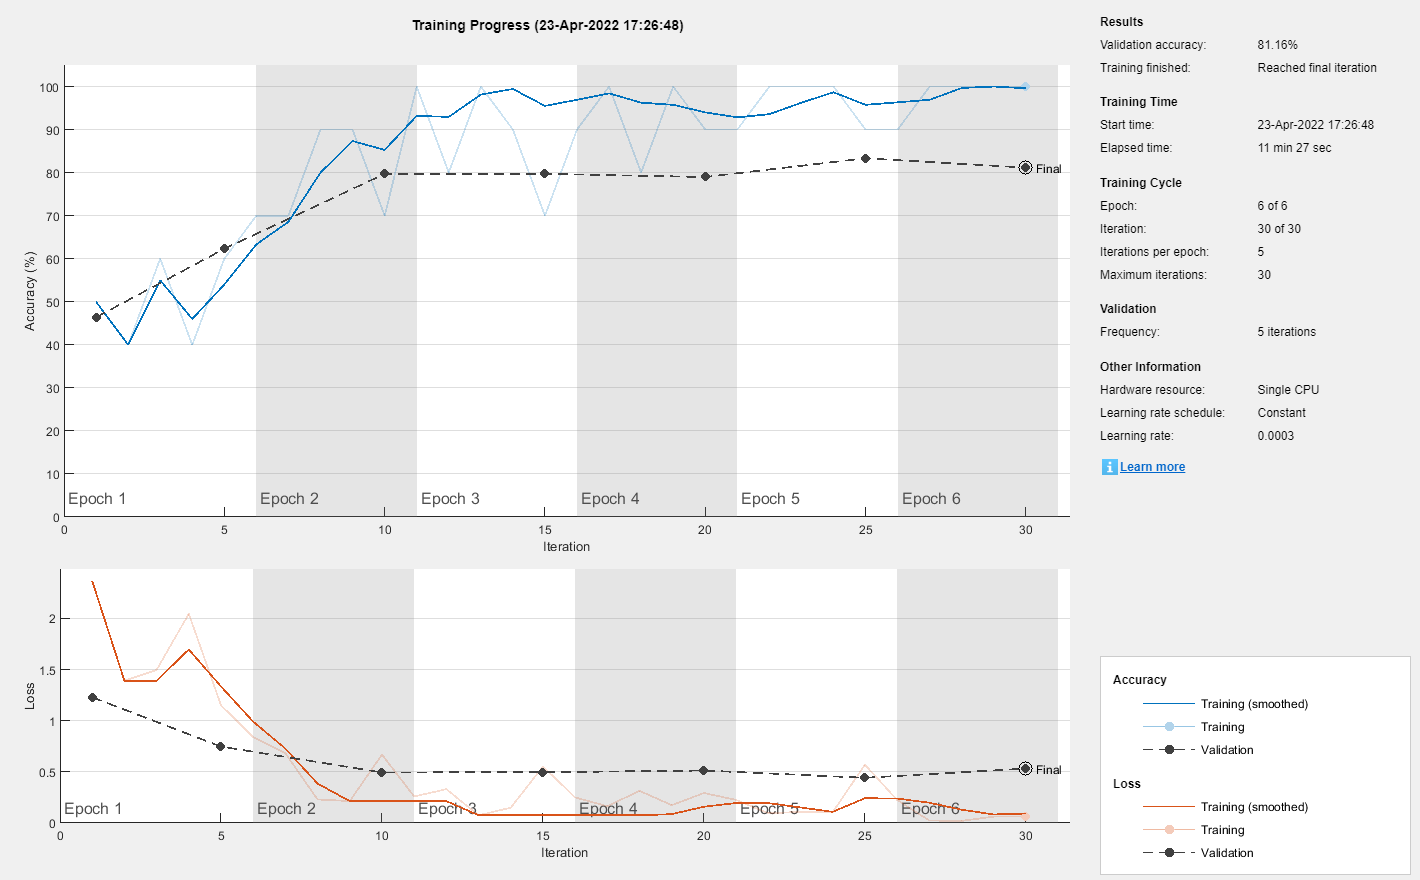

net = trainNetwork(augmentedTrainingSet,lgraph,options);

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.

[YPred,probs] = classify(net,augmentedTestSet);
accuracy = mean(YPred == testSet.Labels)

accuracy = 0.8116

fprintf('The accuracy of resnet-50 in classifying MRI imagis is: %f', accuracy)

The accuracy of resnet-50 in classifying MRI imagis is: 0.811594

Calculate and display  confusion matrix.

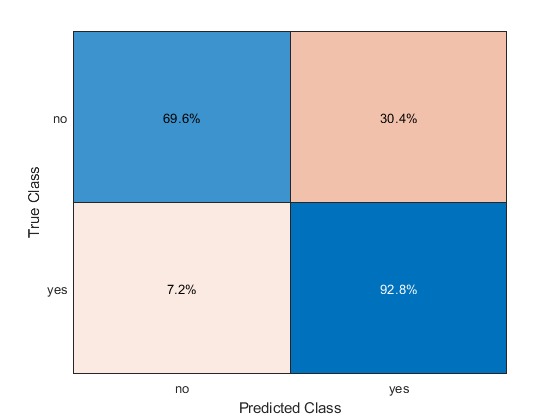

confMat = confusionmat(testSet.Labels, YPred);
confusionchart(testSet.Labels, YPred,'Normalization', 'row-normalized')

Convert confusion matrix into percentage form

confMat = bsxfun(@rdivide,confMat,sum(confMat,2))

confMat =     0.6957    0.3043
    0.0725    0.9275
